# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 노예훈**

**학번**** : 201614627**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/AndrewYaehoon/DSP_assignment-1.git**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

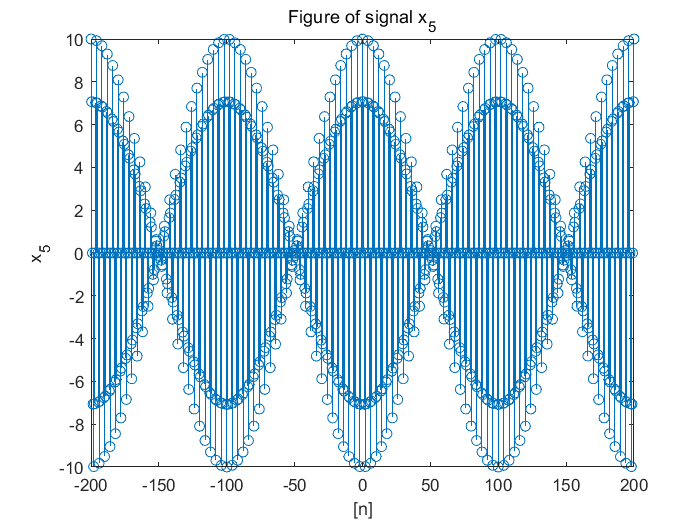


n = [-200 : 0.5 : 200];

x5 = 5*(cos(0.49*pi*n)+cos(0.51*pi*n));

figure()
stem(n , x5);
xlabel('[n]'); ylabel('x_{5}'); title('Figure of signal x_{5}');

2) 

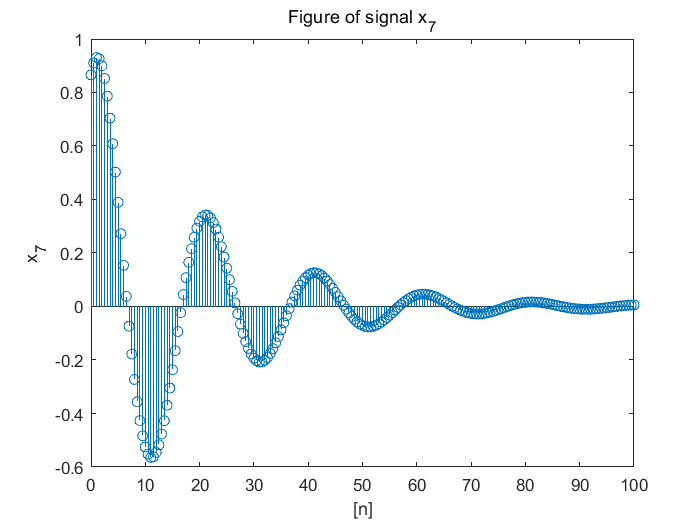


n = [0 : 0.5 : 100];

x7 = exp(-0.05*n).*sin(0.1*pi*n+pi/3);

figure()
stem(n , x7);
xlabel('[n]'); ylabel('x_{7}'); title('Figure of signal x_{7}');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

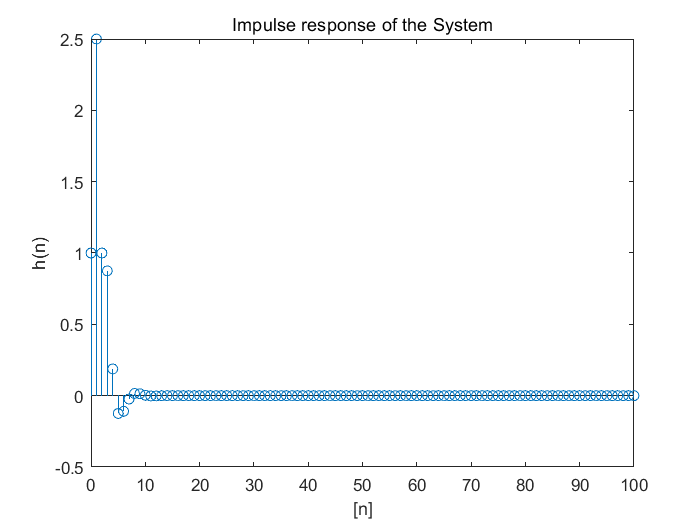

n = 0:100;
b = [1 2 0 1]; a = [1 -0.5 0.25];
h = impz(b, a, n);

figure()
stem(n,h);
xlabel('[n]'); ylabel('h(n)'); title('Impulse response of the System');

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

n = 0:100;
b = [1 2 0 1]; a = [1 -0.5 0.25];
h = impz(b, a, n);
sum(abs(h));
ans

ans = 5.8571

 ans = 5.8571, therefore the system is stable.

3) 만약 이 시스템의 입력이  x(n) = [5+3*cos(0.2*pi*n)+4*sin(0.6*pi*n)]*u(n)이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

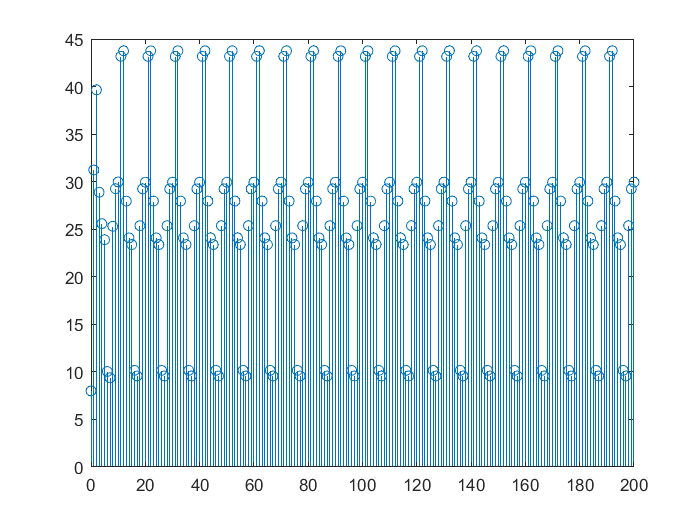

n = 0:200;
b = [1 2 0 1]; a = [1 -0.5 0.25];
x = [5+3*cos(0.2*pi*n)+4*sin(0.6*pi*n)].*stepseq(0,0,200);
y = filter(b, a, x);

figure()
stem(n,y);

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

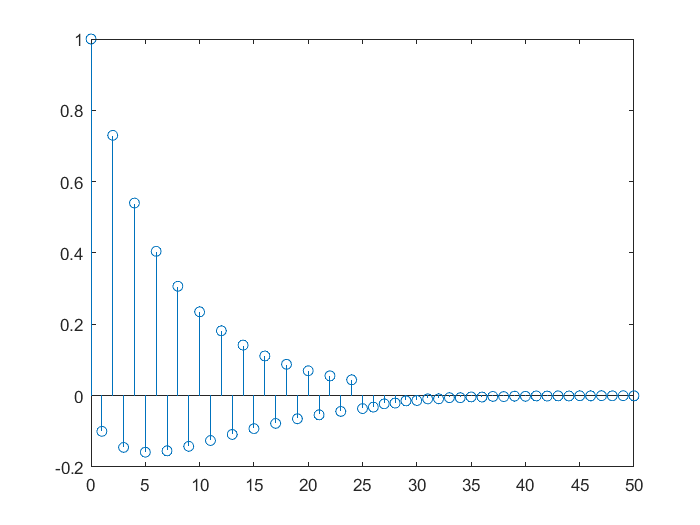

n = 0:25;
x = ((0.8).^n).*stepseq(0,0,25); nx = [0:25];
h = ((-0.9).^n).*stepseq(0,0,25); nh = [0:25];
[y,ny] = conv_m(x,nx,h,nh);

figure()
stem(ny,y);

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

n1 = 0:25;
n2 = 0:50;
x = ((0.8).^n1).*stepseq(0,0,25); h = ((-0.9).^n1).*stepseq(0,0,25);
y = conv(x,h);

figure()
stem(n2,y);

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

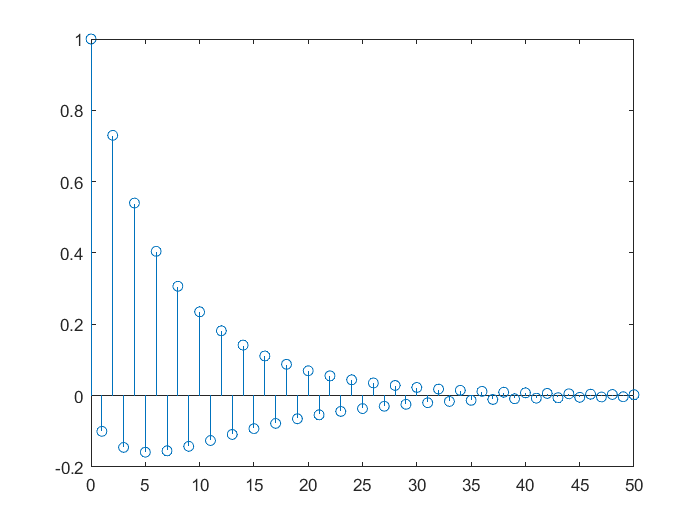


n = 0:50;
x = ((0.8).^n).*stepseq(0,0,50); h = ((-0.9).^n).*stepseq(0,0,50);
y = filter(h,1,x);

figure()
stem(n,y);

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

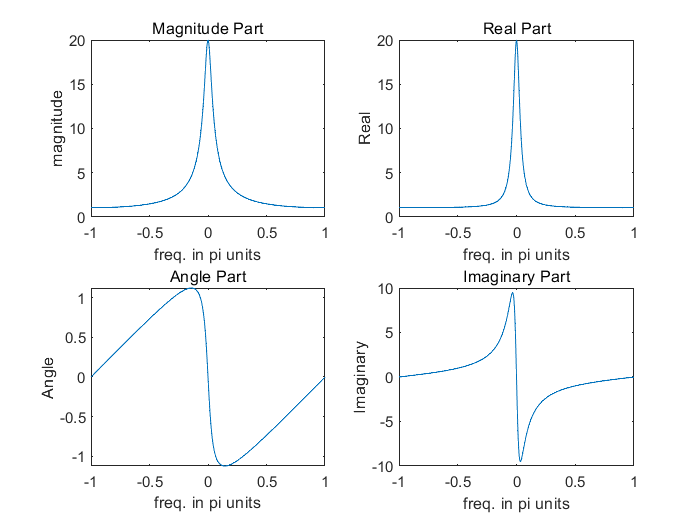

w = [-500:1:500]*pi/500;
H = 2.*exp(j*w) ./ (exp(j*w) - 0.9*ones(1,1001));


magH = abs(H);
angH = angle(H);
realH = real(H);
imagH = imag(H);

subplot(2,2,1); plot(w/pi,magH);
xlabel('freq. in pi units'); ylabel('magnitude');
title('Magnitude Part');

subplot(2,2,3); plot(w/pi,angH); 
xlabel('freq. in pi units'); ylabel('Angle'); 
title('Angle Part');

subplot(2,2,2); plot(w/pi,realH); 
xlabel('freq. in pi units'); ylabel('Real');
title('Real Part');

subplot(2,2,4); plot(w/pi,imagH); 
xlabel('freq. in pi units'); ylabel('Imaginary');
title('Imaginary Part');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

5. (P3.17) 

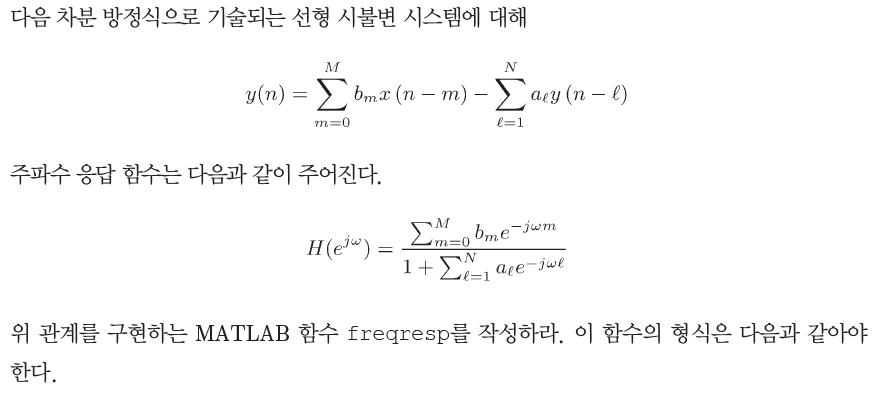

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array

end

function [x,n] = stepseq(n0,n1,n2)
    n = [n1:n2];
    x = [(n-n0) >= 0];
end

function [y,ny] = conv_m(x,nx,h,nh)
nyb = nx(1)+nh(1); nye = nx(length(x)) + nh(length(h));
ny = [nyb:nye];  y = conv(x,h);

end